% Define parameters
%t1 = 1;
%t2 = 1/3;
%m = 0.2;
%w = 0;
Nx = 50;
Ny = 50; % needs to be even to have a whole # of unit cells!
EF = 0;

nplots = 4;

xvals = 0:Nx-1;
yvals = 0:Ny-1;
[X,Y] = meshgrid(xvals,yvals);

x_op_elements = floor((0:Ny*Nx-1)/Ny);
x_op = diag(x_op_elements)

x_op =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y_op_elements = repmat((0:Ny-1), 1, Nx);
y_op = diag(y_op_elements)

y_op =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     3     0     0     0     0     0     0     0     0     0     0     0

Evals_cell = cell(1,nplots);
Estates_cell = cell(1,nplots);
for i = 1:length(Evals_cell)
    temp_evals_array = readmatrix(sprintf('~/Documents/PhD/EBL2/python_files/graphene_hamiltonians_results/w%d_eigenvalues.csv',i-1));
    Evals_cell{i} = diag(temp_evals_array);
    Estates_cell{i} = readmatrix(sprintf('~/Documents/PhD/EBL2/python_files/graphene_hamiltonians_results/w%d_eigenvectors_mat.csv',i-1));
end

S_cell = cell(1,nplots);

for i = 1:length(S_cell)
    S_cell{i} = arrayfun(@(x,y) Spectralfn(EF, x, y, Estates_cell{i}, Evals_cell{i}, Ny), X, Y);
end

AxLabels = xvals;
% Convert each number in the array into a string
CustomAxLabels = string(AxLabels);
% Replace all but the fifth elements by spaces
CustomAxLabels(mod(AxLabels,10) ~= 0) = " ";

'spectral fn'

ans = 'spectral fn'

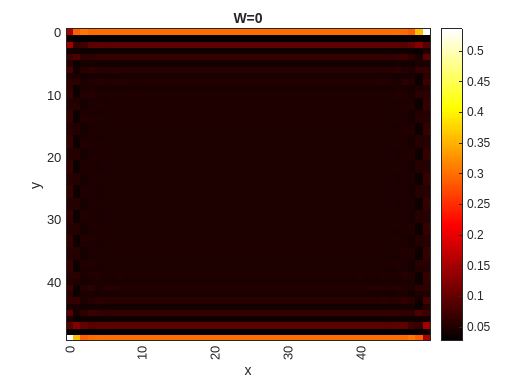

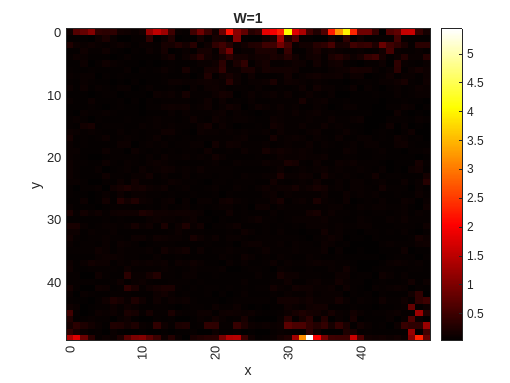

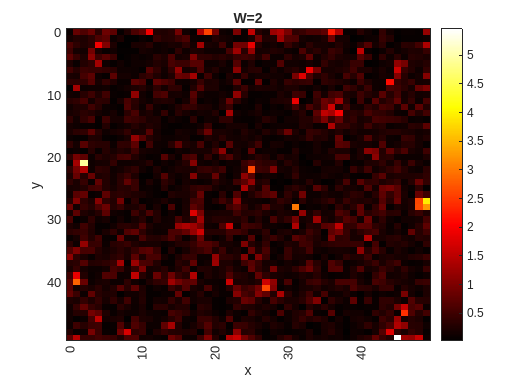

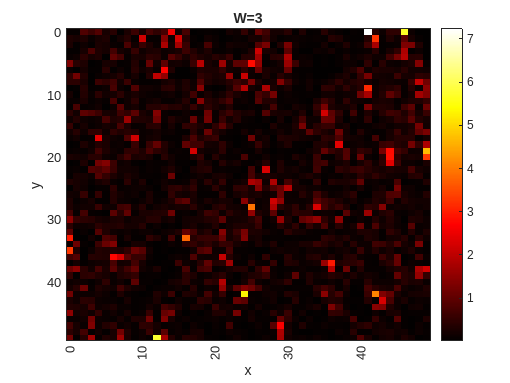

for i = 1:length(S_cell)
    figure;
    heatmap(xvals, yvals, S_cell{i}, 'GridVisible','off', 'XDisplayLabels',CustomAxLabels, 'YDisplayLabels',CustomAxLabels)
    xlabel('x')
    ylabel('y')
    title(['W=' num2str(i-1)]);
    colormap('hot');
    drawnow;
end

function Spectralfn = Spectralfn(E, x, y, Psi, Eig, Ny)
    % Position m of x,y in eigenstate matrixes
    m = 1 + y + Ny * x;
    % Small number for spectral function
    eta = 0.05;
    % Construct cell array for sum in spectral function
    element = cell(1,size(Psi,1));
    for j = 1:size(Psi,1)
        element{j} = (ctranspose(Psi(m,j)) * Psi(m,j)) / (E - real(Eig(j,j)) + 1i * eta);
    end
    Spectralfn = - imag(sum([element{:}]));
end